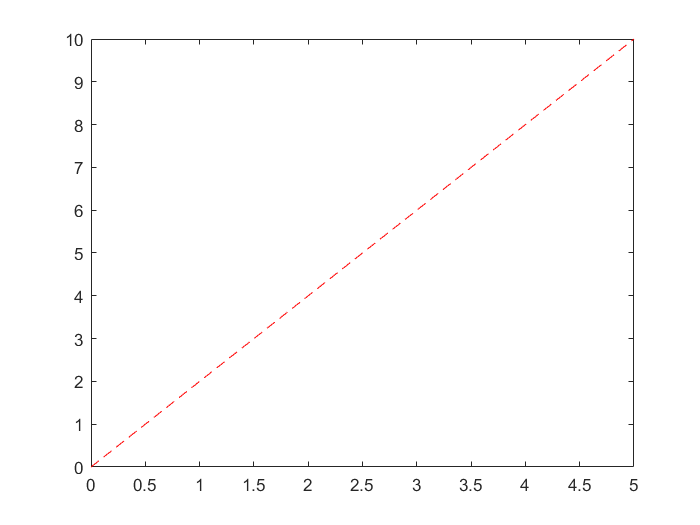

% 2.a
f=@(t,y)2;
y_0=0;
t_0=0;
tfin=5;
tic
[yout1, tout1] = EulerFun(f,t_0,0.1,tfin,y_0);
 plot(tout1,yout1,'r--')

t1 = toc

t1 = 0.0286

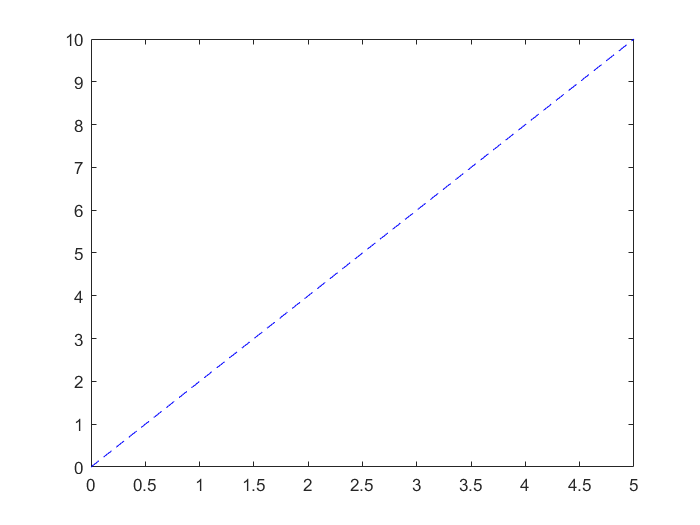

[yout2, tout2] = EulerFun(f,t_0,0.01,tfin,y_0);
 plot(tout2,yout2,'b--')

t2 = toc-t1

t2 = 0.0990

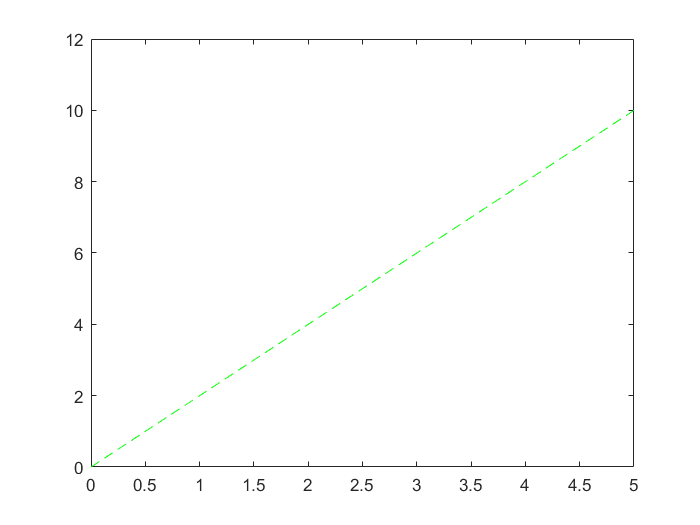

[yout3, tout3] = EulerFun(f,t_0,0.001,tfin,y_0);
 plot(tout3,yout3,'g--')

t3 = toc-t2

t3 = 0.1011

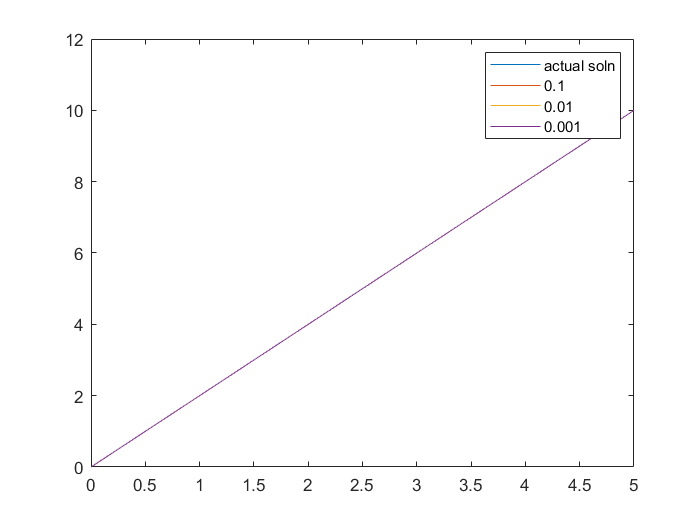


t = linspace(0,5);
y = t.*2;
plot(t,y)

hold on;
plot(tout1,yout1);
plot(tout2,yout2);
plot(tout3,yout3);
legend('actual soln','0.1','0.01','0.001');
hold off;

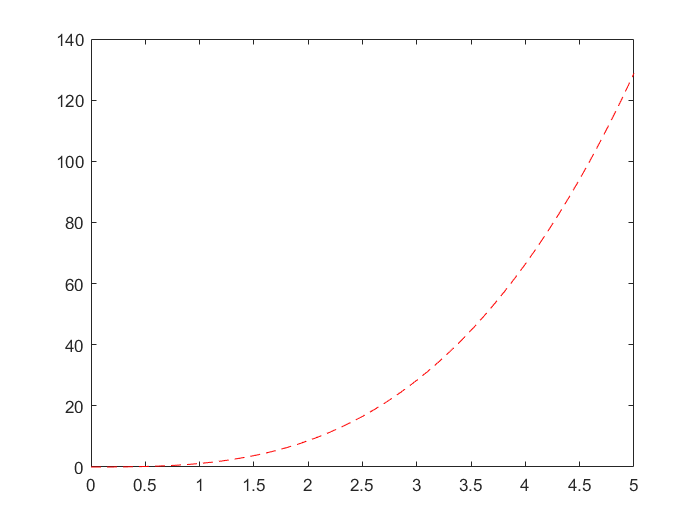

% All the plots are coinciding with each other

% 2.b
f=@(t,y)3*t^2;
y_0=0;
t_0=0;
tfin=5;
tic
[yout1, tout1] = EulerFun(f,t_0,0.1,tfin,y_0);
plot(tout1,yout1,'r--')

Et1 = toc

Et1 = 0.3534

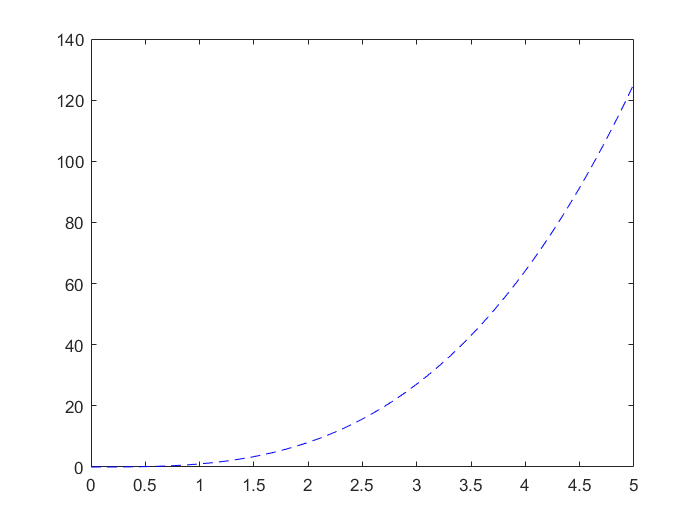

[yout2, tout2] = EulerFun(f,t_0,0.01,tfin,y_0);
plot(tout2,yout2,'b--')

Et2 = toc-Et1

Et2 = 0.1813

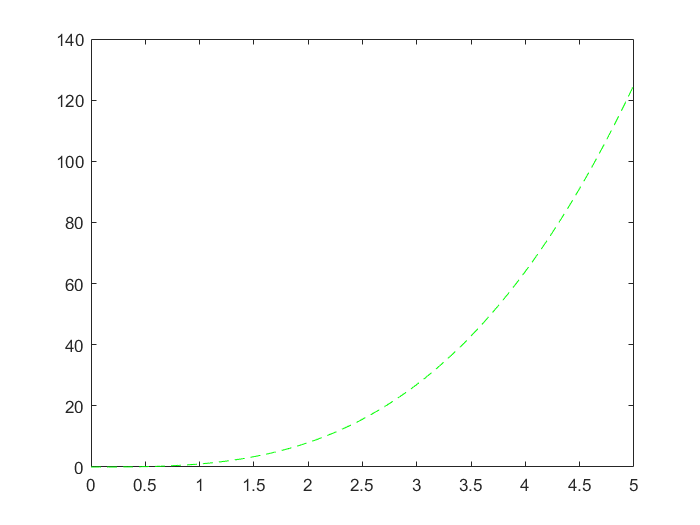

[yout3, tout3] = EulerFun(f,t_0,0.001,tfin,y_0);
plot(tout3,yout3,'g--')

Et3 = toc-Et2

Et3 = 0.4835

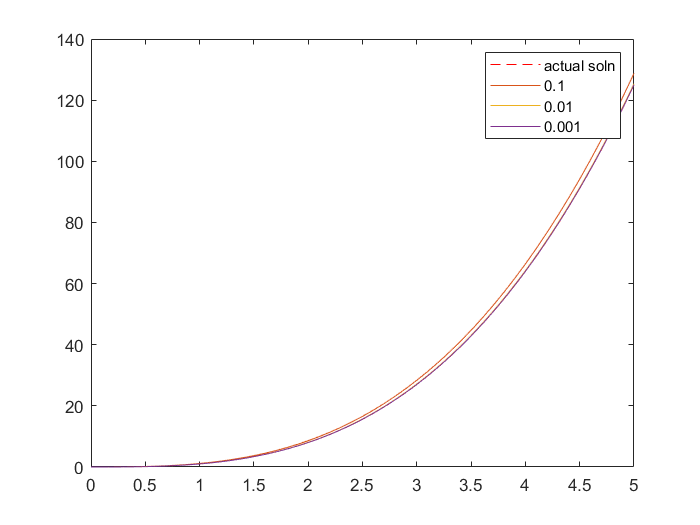


t = linspace(0,5);
y = t.*t.*t;
plot(t,y,'r--')

hold on;
plot(tout1,yout1);
plot(tout2,yout2);
plot(tout3,yout3);
legend('actual soln','0.1','0.01','0.001');
hold off;

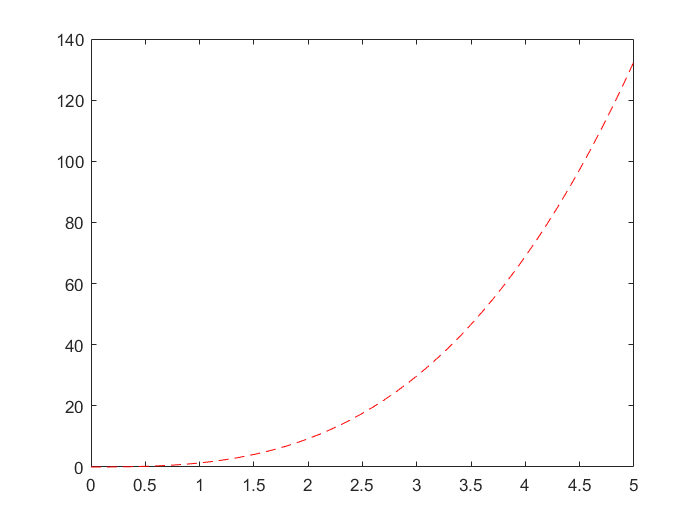


% From the graph obtained it can be observed that as 
% the value of h decreases accuracy increases.

% 4
f=@(t,y)3*t^2;
y_0=0;
t_0=0;
tfin=5;
tic
[yout1, tout1] = RK4(f,t_0,0.1,tfin,y_0);
plot(tout1,yout1,'r--')

Rt_1 = toc

Rt_1 = 0.2378

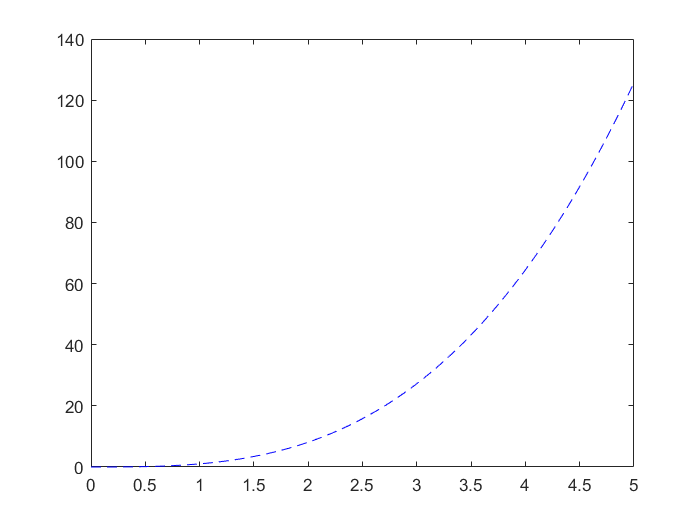

[yout2, tout2] = RK4(f,t_0,0.01,tfin,y_0);
plot(tout2,yout2,'b--')

Rt_2 = toc-Rt_1

Rt_2 = 0.1876

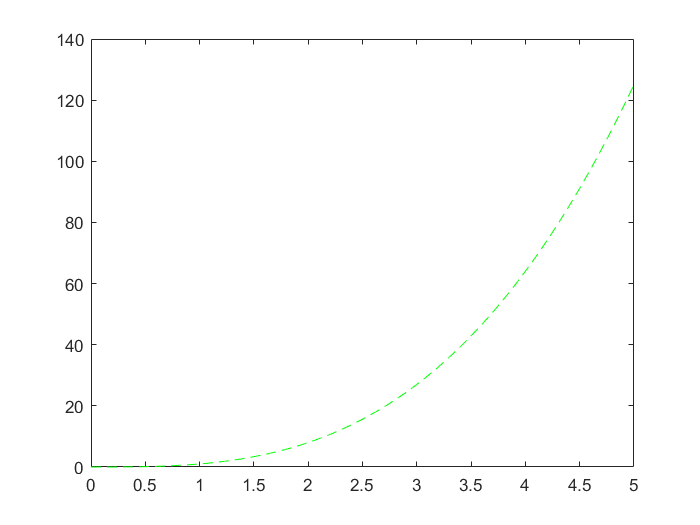

[yout3, tout3] = RK4(f,t_0,0.001,tfin,y_0);
plot(tout3,yout3,'g--')

Rt_3 = toc-Rt_2

Rt_3 = 0.3719

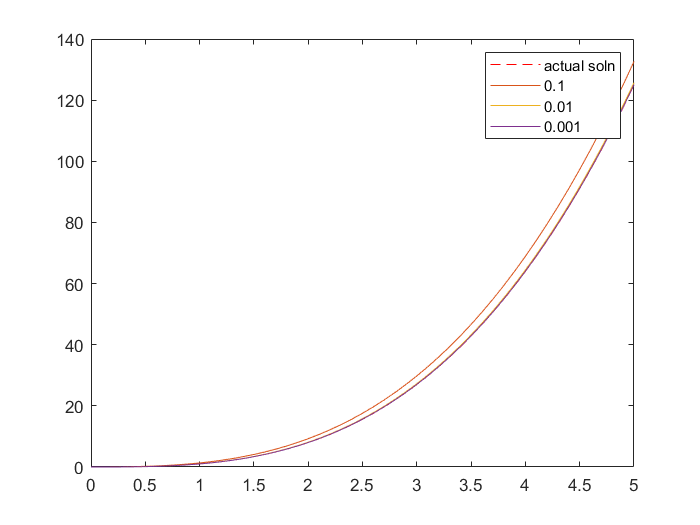


t = linspace(0,5);
y = t.*t.*t;
plot(t,y,'r--')

hold on;
plot(tout1,yout1);
plot(tout2,yout2);
plot(tout3,yout3);
legend('actual soln','0.1','0.01','0.001');
hold off;

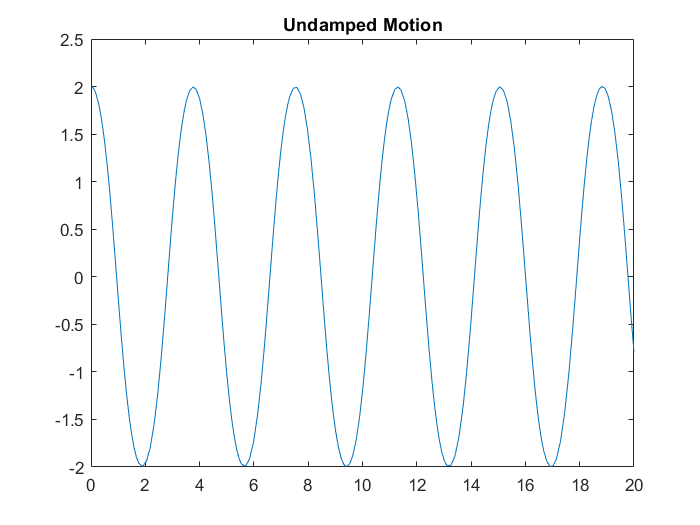

% Table attached seperately


% 5
func1 = @(t,y) [y(2); -(9.8/2)*sin(y(1))]; % define function f(t,y)
[t,y] = ode45(func1, [0,20], [2,0]);
 plot(t,y(:,1))
 y_1 = y(1);
 y_2 = y(2);
 title('Undamped Motion');

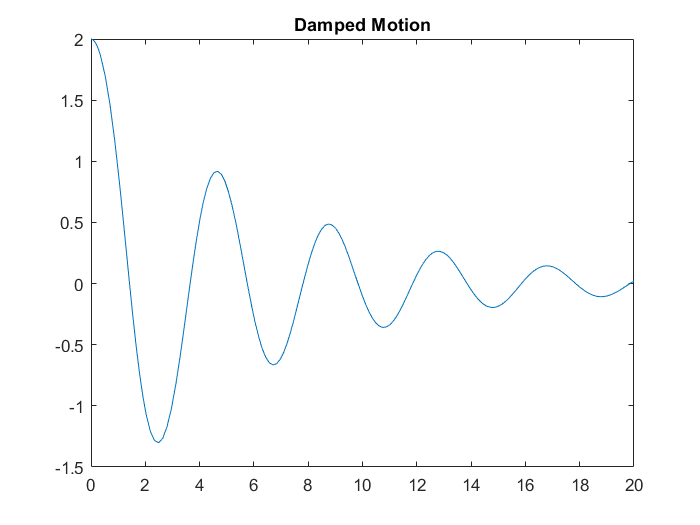


func2 = @(t,y) [y(2); -0.3*y(2)-2.5*sin(y(1))]; % define function f(t,y)
[t,y] = ode45(func2, [0,20], [2,0]);
 plot(t,y(:,1))
 y_1 = y(1);
 y_2 = y(2);
 title('Damped Motion');

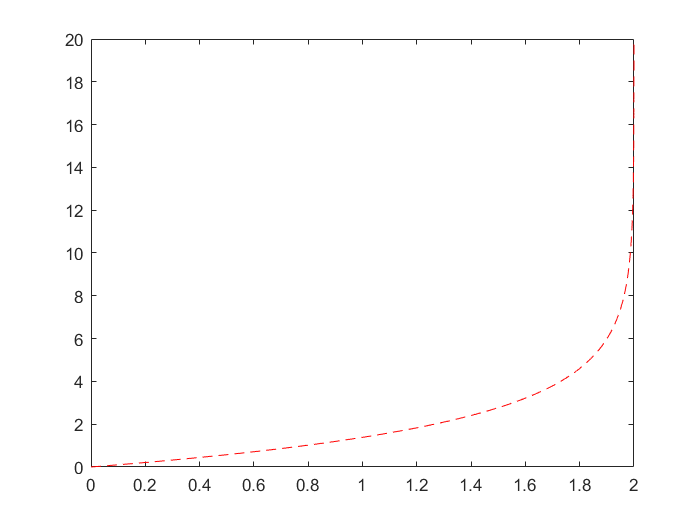


%6
% I(0) = 0 Amp
f_I =@(t,I) (1-0.5*I(1));
I_0=0;
t_0=0;
tfin=20;
[Iout, tout] = RK4(f_I,t_0,0.01,tfin,I_0);
 plot(Iout,tout,'r--')

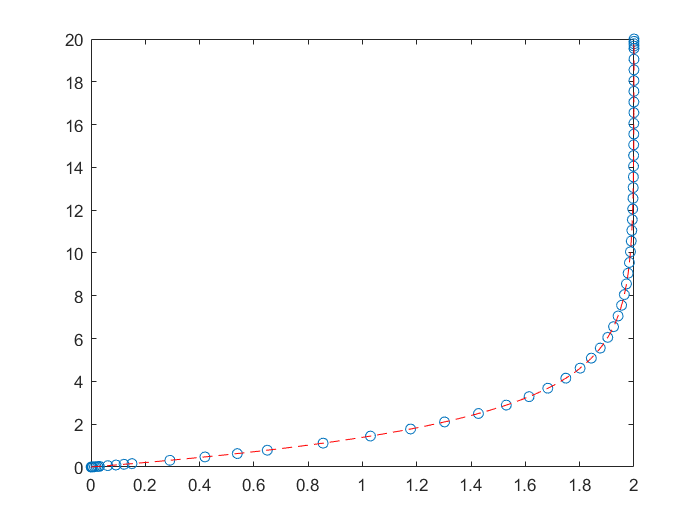

[tcheck, ycheck] = ode45(f_I, [0,20], I_0);
plot(ycheck, tcheck, 'o', Iout,tout,'r--')

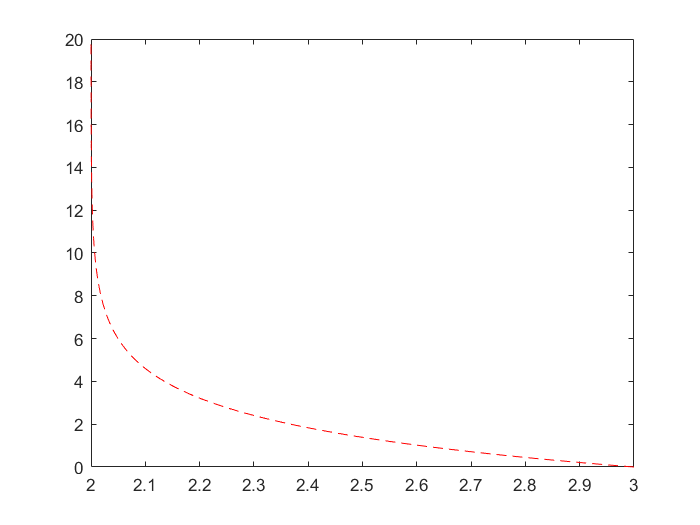


% They are overlapping

%I(0) = 3 Amp
I_0 = 3;
[Iout, tout] = RK4(f_I,t_0,0.01,tfin,I_0);
  plot(Iout,tout,'r--')

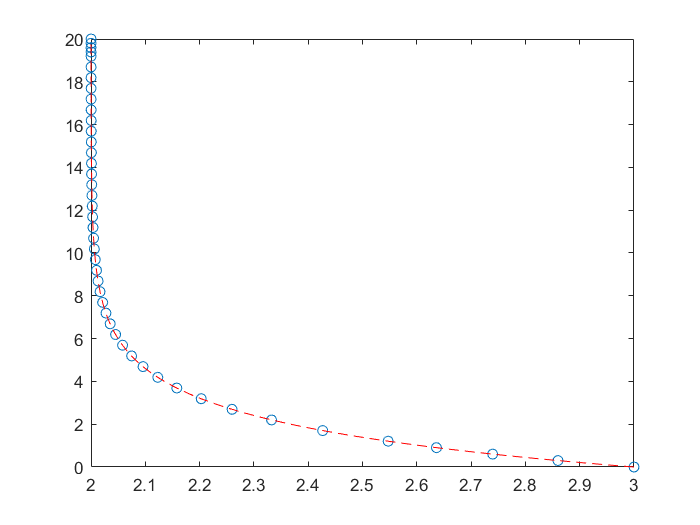

[tcheck, ycheck] = ode45(f_I, [0,20], I_0);
plot(ycheck, tcheck, 'o', Iout,tout,'r--')


% They are overlapping